# Stribeck Curve Fitting from Data

## Import Data

Model_Parameters;
load("exp_torque_curve_calculation.mat");
% load("torque_curve_calculation.mat");


## Data Preparation

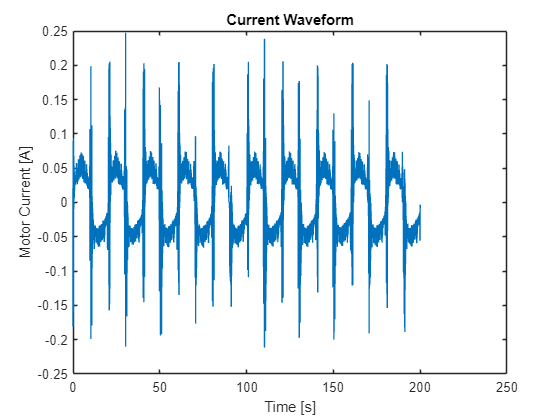

% Data Vector
current_vec = reshape(torque_curve_calculation.signals(1).values, [], 1);   % Current
speed_vec = reshape(torque_curve_calculation.signals(2).values, [], 1);     % Speed
time = torque_curve_calculation.time;                                       % Time
% current_vec = out.torque_curve_sim.signals(1).values;
% speed_vec = out.torque_curve_sim.signals(2).values;
% time = out.torque_curve_sim.time;

plot(time, current_vec)
title('Current Waveform')
xlabel('Time [s]')
ylabel('Motor Current [A]')

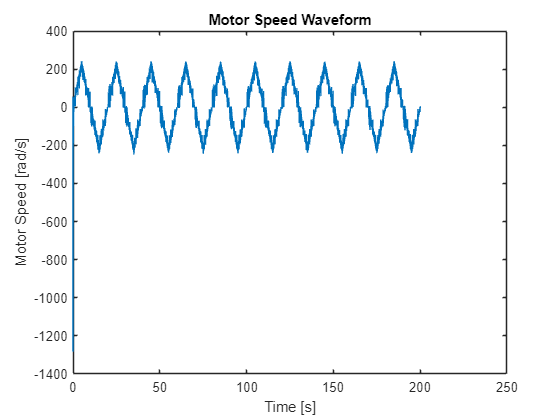

plot(time, speed_vec)
title('Motor Speed Waveform')
xlabel('Time [s]')
ylabel('Motor Speed [rad/s]')

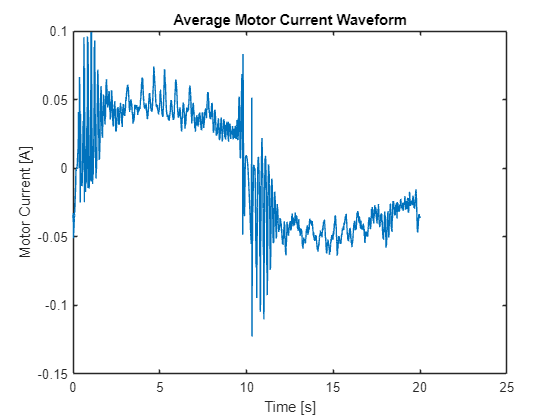

% Reshape and Mean
mean_current_vec = mean(reshape(current_vec(1:200000), 20000, []), 2);
mean_speed_vec = mean(reshape(speed_vec(1:200000), 20000, []), 2);

plot(time(1:20000), mean_current_vec)
title('Average Motor Current Waveform')
xlabel('Time [s]')
ylabel('Motor Current [A]')

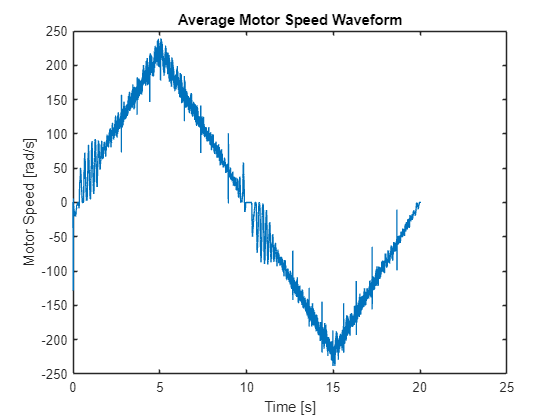


plot(time(1:20000), mean_speed_vec)
title('Average Motor Speed Waveform')
xlabel('Time [s]')
ylabel('Motor Speed [rad/s]')

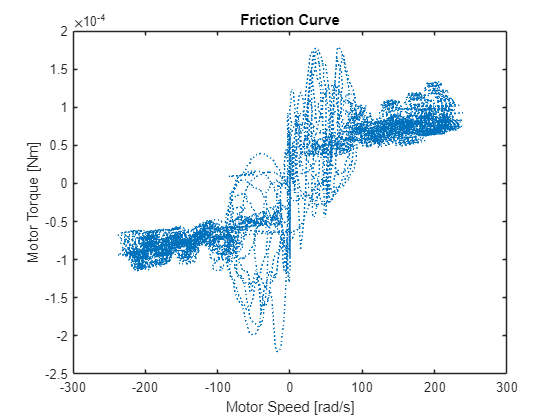

plot(mean_speed_vec, mean_current_vec*motor.Kphi, ':')
title('Friction Curve')
xlabel('Motor Speed [rad/s]')
ylabel('Motor Torque [Nm]')

## Data Fitting Code

% Compare the fitted curve equation with the data on the same graph
% treat positive and negative quadrant as 2 different fittings
% treat hysteresis as 2 different fitting